clear all; close all; 
f1 = @(x) 0.01 * sin(10 .* x) + (0.07 * x.^2 - 0.4).^ 2;
f2 = @(x) x.^4 + x.^3 - x.^2 + 2*x - 6

f2 = function_handle with value:
    @(x)x.^4+x.^3-x.^2+2*x-6


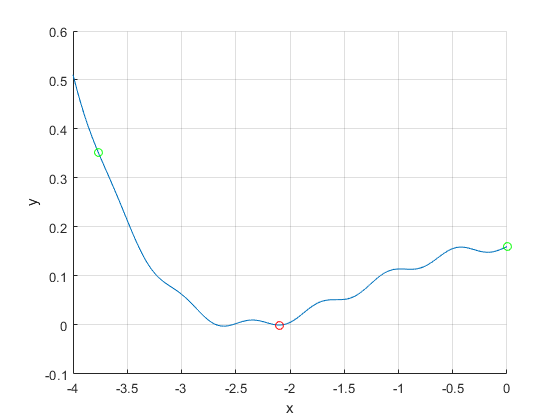


x0 = -4:0.01:0;
y0 = f1(x0);
a0 = 0;
a1 = -3.7648;

min = gold_div(a0, a1, f1, 0.01, 1000);

figure(1)
hold on
plot(x0, y0)
scatter([a0, a1], [f1(a0), f1(a1)], 'green')
scatter(min, f1(min), 'red')
xlabel('x')
ylabel('y')
grid on;

function x = gold_div(a_s, b_s, func, eps, Nmax)
    
    alpha = (sqrt(5) - 1)/2;
    
    c0 = b_s - alpha*(b_s - a_s);
    d0 = a_s + alpha*(b_s - a_s);
    
    i = 0;
    
    a_i = a_s;
    b_i = b_s;
    c_i = c0;
    d_i = d0;
    
    while abs(b_i - a_i) > eps
       if func(c_i) < func(d_i)
            %a_i = a_i
            b_i = d_i;
            d_i = c_i;
            c_i = b_i - alpha * (b_i - a_i);
           
       else
            a_i = c_i;
            %b_i = b_i;
            c_i = d_i;
            d_i = a_i + alpha*(b_i - a_i);    
       end
       i = i + 1;
       if i > Nmax
          x = false; 
       end
       x = (a_i + b_i)/2;
    end
    
end